clear

addpath('functions\')

#### Compute $\Phi$

Model = myModel;

freqs = [1000 2000 4000 16000]; % (Hz)

freqs = reshape(freqs, 1,1,[]);
M = size(Model.sensors.positions,2);
N = size(Model.voxels.center,2);
Phi = zeros(M, N, length(freqs));

for k = 1:length(freqs)
    tic
    [S_sigma, S_mu] = Model.Sensitivity(freqs(k));
    sigma = Model.voxels.sigma;
    mur   = Model.voxels.mur;
    mu0 = 4*pi * 1e-7;
    Phi(:,:,k) = S_sigma .* -sigma + S_mu .* (1 - mur) * mu0;
    fprintf('Compute %g Hz sensitivity took %.2f seconds\n', freqs(k), toc)
end

Compute 1000 Hz sensitivity took 68.50 seconds
Compute 2000 Hz sensitivity took 36.49 seconds
Compute 4000 Hz sensitivity took 36.17 seconds
Compute 16000 Hz sensitivity took 36.28 seconds


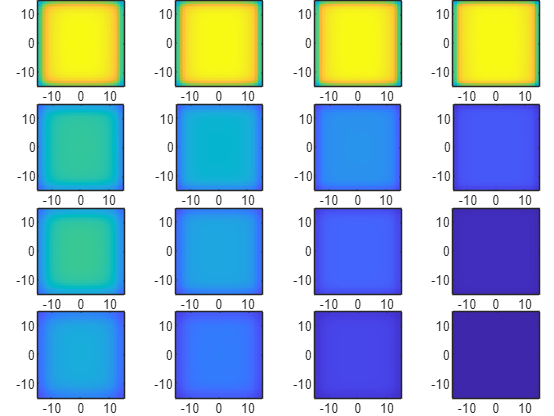


voxels_center = Model.voxels.center;

fname = sprintf('data/Phi_%s.mat', datetime('now','Format','MMdd-HHmm'));
save(fname, 'freqs','Phi','voxels_center', "-v7.3");

plot_sensitivity(fname)